Q3

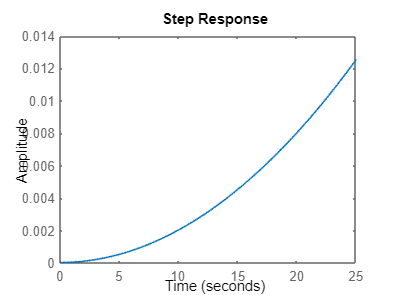

clc
clear
close

% Variable definitions and system creation
m = 5; % Slider mass
M = 25000; % Container mass
l = 8; % Rope length 
g = 9.81; % Acceleration due to gravity

% System Matrix
A = [0 1 0 0; 0 0 (M*g/m) 0; 0 0 0 1; 0 0 -((1 + (M/m))*g/l) 0];
B = [0; 1/m; 0; -1/(m*l)];
C = [1 0 0 0];
D = 0;

[num,den] = ss2tf(A,B,C,D);
sys = tf(num,den);
step(sys);